warning('off')

dataset = DLX;
DLXsepPCC = [];
DLXexpPCC = [];
n = 20;
for i = 1:length(dataset)
    m1 = dataset{i}{1};
    m2 = dataset{i}{2};
    % sep
    [~,b1]=sort(sum(m1.MS{1}.S, 2),'descend');
    [~,b2]=sort(sum(m2.MS{1}.S, 2),'descend');
    goodCellSorted1 = m1.MS{1}.goodCellVec(b1);
    goodCellSorted2 = m2.MS{1}.goodCellVec(b2);
    b1 = b1(goodCellSorted1>0);
    b2 = b2(goodCellSorted2>0);
    % top 50 and bottom 50
    
    top1 = zscore(m1.MS{1}.FiltTraces(:,b1(1:n)));
    top2 = zscore(m2.MS{1}.FiltTraces(:,b2(1:n)));
    bottom1 = zscore(m1.MS{1}.FiltTraces(:,b1(end-n+1:end)));
    bottom2 = zscore(m2.MS{1}.FiltTraces(:,b2(end-n+1:end)));
    mlen = min(size(top1,1),size(top2,1));
    cor_top = corr(mean(top1(1:mlen,:),2),mean(top2(1:mlen,:),2));
    cor_bottom = corr(mean(bottom1(1:mlen,:),2),mean(bottom2(1:mlen,:),2));
    DLXsepPCC = [DLXsepPCC;cor_top,cor_bottom];
    
    % exp
    [~,b1]=sort(sum(m1.MS{2}.S, 2),'descend');
    [~,b2]=sort(sum(m2.MS{2}.S, 2),'descend');
    goodCellSorted1 = m1.MS{2}.goodCellVec(b1);
    goodCellSorted2 = m2.MS{2}.goodCellVec(b2);
    b1 = b1(goodCellSorted1>0);
    b2 = b2(goodCellSorted2>0);
    % top 50 and bottom 50
    
    top1 = zscore(m1.MS{2}.FiltTraces(:,b1(1:n)));
    top2 = zscore(m2.MS{2}.FiltTraces(:,b2(1:n)));
    bottom1 = zscore(m1.MS{2}.FiltTraces(:,b1(end-n+1:end)));
    bottom2 = zscore(m2.MS{2}.FiltTraces(:,b2(end-n+1:end)));
    mlen = min(size(top1,1),size(top2,1));
    cor_top = corr(mean(top1(1:mlen,:),2),mean(top2(1:mlen,:),2));
    cor_bottom = corr(mean(bottom1(1:mlen,:),2),mean(bottom2(1:mlen,:),2));
    DLXexpPCC = [DLXexpPCC;cor_top,cor_bottom];
    
end

dataset = CMK;
CMKsepPCC = [];
CMKexpPCC = [];
n = 50;
for i = 1:length(dataset)
    m1 = dataset{i}{1};
    m2 = dataset{i}{2};
    % sep
    [~,b1]=sort(sum(m1.MS{1}.S, 2),'descend');
    [~,b2]=sort(sum(m2.MS{1}.S, 2),'descend');
    goodCellSorted1 = m1.MS{1}.goodCellVec(b1);
    goodCellSorted2 = m2.MS{1}.goodCellVec(b2);
    b1 = b1(goodCellSorted1>0);
    b2 = b2(goodCellSorted2>0);
    % top 50 and bottom 50
    
    top1 = zscore(m1.MS{1}.FiltTraces(:,b1(1:n)));
    top2 = zscore(m2.MS{1}.FiltTraces(:,b2(1:n)));
    bottom1 = zscore(m1.MS{1}.FiltTraces(:,b1(end-n+1:end)));
    bottom2 = zscore(m2.MS{1}.FiltTraces(:,b2(end-n+1:end)));
    mlen = min(size(top1,1),size(top2,1));
    cor_top = corr(mean(top1(1:mlen,:),2),mean(top2(1:mlen,:),2));
    cor_bottom = corr(mean(bottom1(1:mlen,:),2),mean(bottom2(1:mlen,:),2));
    CMKsepPCC = [CMKsepPCC;cor_top,cor_bottom];
    
    % exp
    [~,b1]=sort(sum(m1.MS{2}.S, 2),'descend');
    [~,b2]=sort(sum(m2.MS{2}.S, 2),'descend');
    goodCellSorted1 = m1.MS{2}.goodCellVec(b1);
    goodCellSorted2 = m2.MS{2}.goodCellVec(b2);
    b1 = b1(goodCellSorted1>0);
    b2 = b2(goodCellSorted2>0);
    % top 50 and bottom 50
    
    top1 = zscore(m1.MS{2}.FiltTraces(:,b1(1:n)));
    top2 = zscore(m2.MS{2}.FiltTraces(:,b2(1:n)));
    bottom1 = zscore(m1.MS{2}.FiltTraces(:,b1(end-n+1:end)));
    bottom2 = zscore(m2.MS{2}.FiltTraces(:,b2(end-n+1:end)));
    mlen = min(size(top1,1),size(top2,1));
    cor_top = corr(mean(top1(1:mlen,:),2),mean(top2(1:mlen,:),2));
    cor_bottom = corr(mean(bottom1(1:mlen,:),2),mean(bottom2(1:mlen,:),2));
    CMKexpPCC = [CMKexpPCC;cor_top,cor_bottom];
    
end

figure,boxplot([CMKsepPCC,CMKexpPCC])

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

set(gca,'xticklabel',{'sep_bottom20', 'sep_top20', 'exp_bottom20','exp_top20'})
figure, boxplot([DLXsepPCC,DLXexpPCC])
set(gca,'xticklabel',{'sep_bottom20', 'sep_top20', 'exp_bottom20','exp_top20'})

% pairwise correlation
CMK_within_sep = [];
CMK_within_exp = [];
dataset = CMK;
for i = 1:length(dataset)
    %sep
    m1 = dataset{i}{1};
    m2 = dataset{i}{2};
    tempcor = corr(zscore(m1.MS{1}.FiltTraces(:,m1.MS{1}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor(tempcor==0) = [];
    CMK_within_sep = [CMK_within_sep; tempcor];
    tempcor = corr(zscore(m2.MS{1}.FiltTraces(:,m2.MS{1}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor = tempcor(tempcor~=0);
    CMK_within_sep = [CMK_within_sep; tempcor];
    tempcor = corr(zscore(m1.MS{2}.FiltTraces(:,m1.MS{2}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor(tempcor==0) = [];
    CMK_within_exp = [CMK_within_exp; tempcor];
    tempcor = corr(zscore(m2.MS{2}.FiltTraces(:,m2.MS{2}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor = tempcor(tempcor~=0);
    CMK_within_exp = [CMK_within_exp; tempcor];
end

% pairwise correlation
DLX_within_sep = [];
DLX_within_exp = [];
dataset = DLX;
for i = 1:length(dataset)
    %sep
    m1 = dataset{i}{1};
    m2 = dataset{i}{2};
    tempcor = corr(zscore(m1.MS{1}.FiltTraces(:,m1.MS{1}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor(tempcor==0) = [];
    DLX_within_sep = [DLX_within_sep; tempcor];
    tempcor = corr(zscore(m2.MS{1}.FiltTraces(:,m2.MS{1}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor = tempcor(tempcor~=0);
    DLX_within_sep = [DLX_within_sep; tempcor];
    tempcor = corr(zscore(m1.MS{2}.FiltTraces(:,m1.MS{2}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor = tempcor(tempcor~=0);
    DLX_within_exp = [DLX_within_exp; tempcor];
    tempcor = corr(zscore(m2.MS{2}.FiltTraces(:,m2.MS{2}.goodCellVec>0)));
    tempcor = tril(tempcor,-1);
    tempcor = tempcor(:);
    tempcor(tempcor==0) = [];
    DLX_within_exp = [DLX_within_exp; tempcor];
end

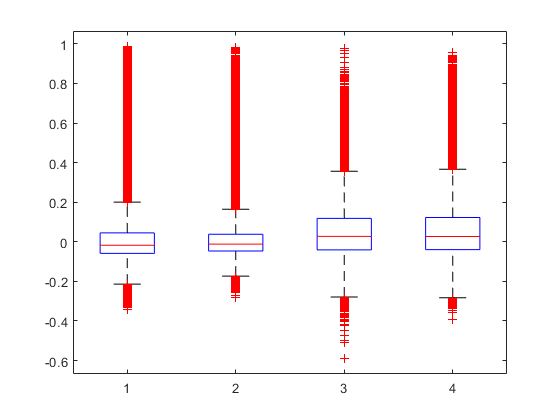

figure, boxplot([CMK_within_sep;CMK_within_exp;DLX_within_sep;DLX_within_exp],...
    [ones(length(CMK_within_sep),1);ones(length(CMK_within_exp),1)*2;...
    ones(length(DLX_within_sep),1)*3;ones(length(DLX_within_exp),1)*4]);

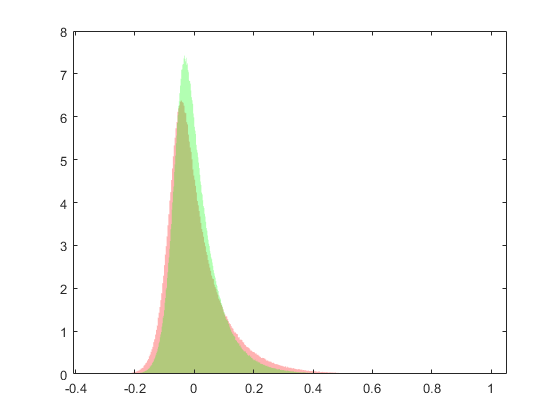

figure, histogram(CMK_within_sep,'FaceColor','red','FaceAlpha',0.3,'EdgeColor','none','EdgeAlpha',0.3,'Normalization','pdf');
hold on, histogram(CMK_within_exp,'FaceColor','green','FaceAlpha',0.3,'EdgeColor','none','EdgeAlpha',0.3,'Normalization','pdf')

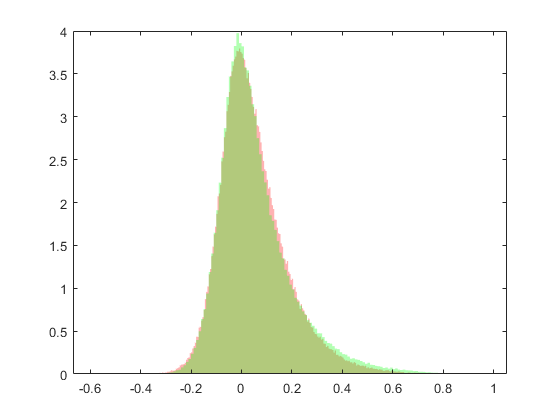

figure, histogram(DLX_within_sep,'FaceColor','red','FaceAlpha',0.3,'EdgeColor','none','EdgeAlpha',0.3,'Normalization','pdf');
hold on, histogram(DLX_within_exp,'FaceColor','green','FaceAlpha',0.3,'EdgeColor','none','EdgeAlpha',0.3,'Normalization','pdf')

% PCA for normalized cell number
n = 50; % normalize to this cell count 
dataset = CMK;
PCA_var_exp = [];
PCA_var_sep = [];
for i = 1:length(dataset)
    m1 = dataset{i}{1};
    m2 = dataset{i}{2};
    
    m1sep = zscore(m1.MS{1}.FiltTraces(:,m1.MS{1}.goodCellVec>0));
    m1exp = zscore(m1.MS{2}.FiltTraces(:,m1.MS{2}.goodCellVec>0));
    m2sep = zscore(m2.MS{1}.FiltTraces(:,m2.MS{1}.goodCellVec>0));
    m2exp = zscore(m2.MS{2}.FiltTraces(:,m2.MS{2}.goodCellVec>0));
    m1sepmean = [];
    m1expmean = [];
    m2sepmean = [];
    m2expmean = [];
    parfor j = 1:100 % 1000 random sample
        [~,~,~,~,m1sep_explain] = pca(datasample(m1sep,n,2));
        [~,~,~,~,m2sep_explain] = pca(datasample(m2sep,n,2));
        [~,~,~,~,m1exp_explain] = pca(datasample(m1exp,n,2));
        [~,~,~,~,m2exp_explain] = pca(datasample(m2exp,n,2));
        m1sepmean = [m1sepmean,m1sep_explain];
        m1expmean = [m1expmean,m1exp_explain];
        m2sepmean = [m2sepmean,m2sep_explain];
        m2expmean = [m2expmean,m2exp_explain];
    end
    PCA_var_sep = [PCA_var_sep, mean(m1sepmean,2), mean(m2sepmean,2)];
    PCA_var_exp = [PCA_var_exp, mean(m1expmean,2), mean(m2expmean,2)];
    disp(i)    
    
end

Using only the first 43 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>

     1



Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 45 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 47 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 45 components to compute TSQUARED.
> In pca>

     2



Using only the first 44 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 49 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 49 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 45 components to compute TSQUARED.
> In pca>

     3



Using only the first 48 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 45 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>

     4



Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 47 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 43 components to compute TSQUARED.
> In pca>

     5



Using only the first 45 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 49 components to compute TSQUARED.
> In pca>

     6



Using only the first 45 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 47 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 44 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 44 components to compute TSQUARED.
> In pca>

     7



Using only the first 40 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 45 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 44 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>

     8



Using only the first 45 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 47 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>

     9



Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 47 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 43 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>

    10



Using only the first 40 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 47 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>

    11



Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 40 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>

    12



Using only the first 47 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 48 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In parallel_function>make_general_channel/channel_general (line 845)
In remoteParallelFunction (line 67)
Using only the first 46 components to compute TSQUARED.
> In pca>

    13



CMK_PCA_var_sep = PCA_var_sep;
CMK_PCA_var_exp = PCA_var_exp;

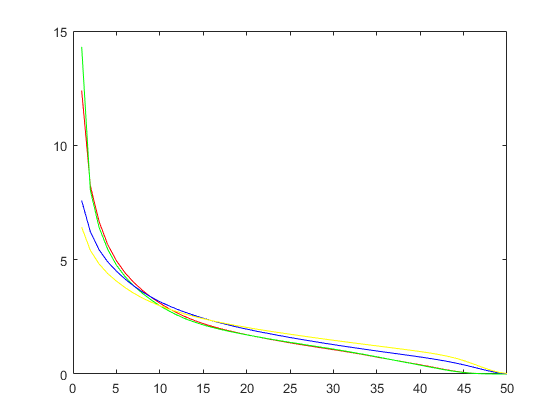

figure, plot(mean(DLX_PCA_var_sep,2),'r'), hold on, plot(mean(DLX_PCA_var_exp,2),'g');
plot(mean(CMK_PCA_var_sep,2),'b'), hold on, plot(mean(CMK_PCA_var_exp,2),'y');

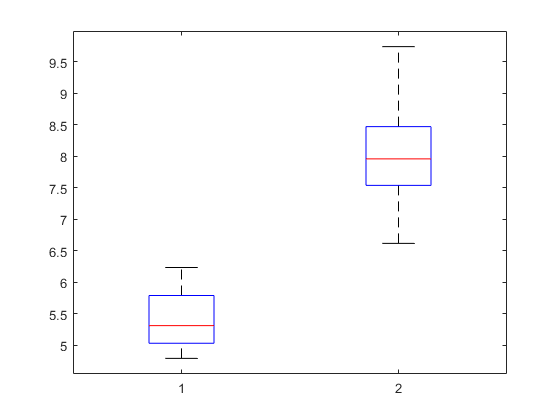

top3sep = transpose([CMK_PCA_var_sep(1:3,:),DLX_PCA_var_sep(1:3,:)]);
top3exp = transpose([CMK_PCA_var_exp(1:3,:),DLX_PCA_var_exp(1:3,:)]);
grp = [ones(26,1);ones(32,1)*2];
figure, boxplot(top3exp(:,2),grp);